# Import data from text file

## Set up the Import Options and import the data

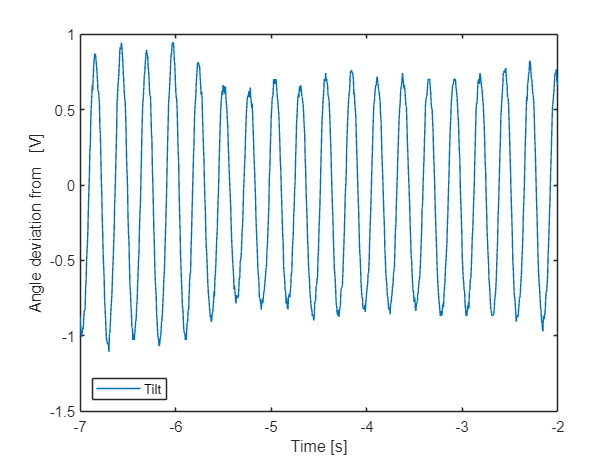

clear all;
clf;
opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["xaxis", "VarName2", "VarName3"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
scoperb62 = readtable("oscilloscope\scope_vh_2.csv", opts); 
scoperb62(:,"VarName2") = scoperb62(:,"VarName2")-1.65; % fix centerpoint
scoperb62(:,"VarName3") = scoperb62(:,"VarName3")-1.65;

plot(scoperb62,"xaxis","VarName2")
hold on
%plot(scoperb62,"xaxis","VarName3")
ylabel('Angle deviation from   [V]')
xlabel('Time [s]')
legend({'Tilt'},'Location','southwest')
xlim([-7 -2])
hold off

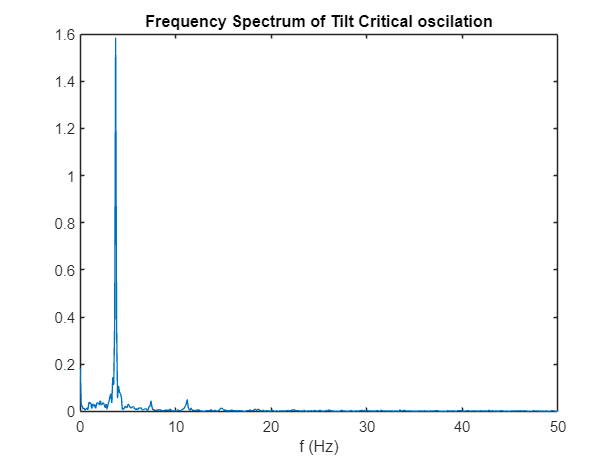

array = table2array(scoperb62(:,"VarName2"));
% Remove NaN entries
cleanedArray = array(~isnan(array));

Fs = 100;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 10*Fs;             % Length of signal

Y = fft(cleanedArray);

P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);

f = Fs*(0:(L/2))/L;

plot(f,P1) 
title("Frequency Spectrum of Tilt Critical oscilation")
xlabel("f (Hz)")

## Clear temporary variables

clear opts

# Import data from text file

## Set up the Import Options and import the data

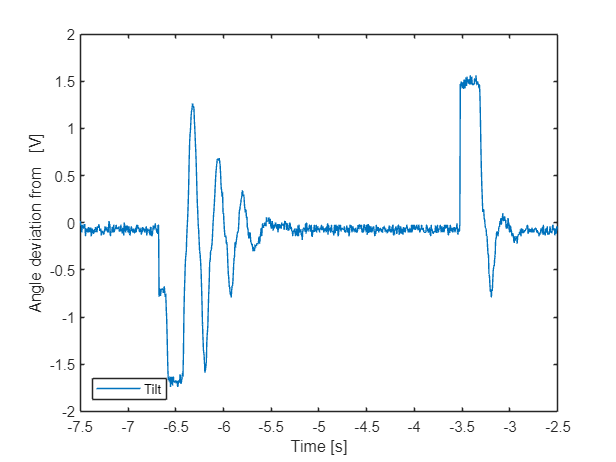

opts = delimitedTextImportOptions("NumVariables", 3);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["xaxis", "VarName2", "VarName3"];
opts.VariableTypes = ["double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
scoperb62 = readtable("oscilloscope\scope_tilt_nopid.csv", opts); 
scoperb62(:,"VarName2") = scoperb62(:,"VarName2")-1.65; % fix centerpoint
scoperb62(:,"VarName3") = scoperb62(:,"VarName3")-1.65;

plot(scoperb62,"xaxis","VarName2")
hold on
%plot(scoperb62,"xaxis","VarName3")
ylabel('Angle deviation from   [V]')
xlabel('Time [s]')
legend({'Tilt'},'Location','southwest')
xlim([-7.5 -2.5])
hold off

## Clear temporary variables

clear opts

